# ACM 11 Week 9 In-Class Exercise 1

## Holdout validation of polynomial regression

#### **(0) Names of all group members: **

Kyle McGraw, Dallas Taylor

In this exercise, we will explore using holdout validation to assess fitting polynomial models to data. We will suppose that our data correspond to noisy measurements of some underlying process. The underlying process $f\left(x\right)$ maps inputs $x$ to outputs $y$. However, when we measure the process at $x$ we get a measurement that is corrupted by a zero-mean Gaussian random variable.

The code below has three different underlying process models $f\left(x\right)$. It generates 40 data points, and assigns 30 data points to be the training set and the remaining 10 to be the holdout or test set. We plot the function $f$ together with the generated data to visualize the function and the data.

**(1) Run the code block below a few times for each of the different functions **$f$ **to get a feel for how the data relate to the underlying function.**

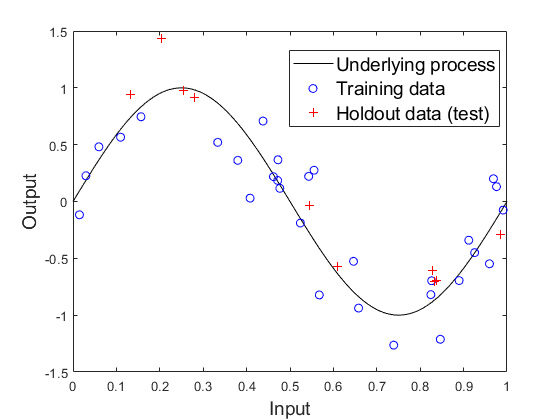

clear

f = @(x) sin(2*pi*x);

N = 40;
N_train = 30;

x_data = rand(N,1);
y_data = f(x_data) + 0.25*randn(N,1);

x_train = x_data(1:N_train);
x_test = x_data(N_train+1:end);

y_train = y_data(1:N_train);
y_test = y_data(N_train+1:end);

xx = linspace(0,1);
figure(1); clf
plot(xx,f(xx),'k'); hold on
plot(x_train,y_train,'bo')
plot(x_test,y_test,'r+')
legend('Underlying process','Training data','Holdout data (test)',...
    'FontSize',14,'Location','best')
xlabel('Input','FontSize',14)
ylabel('Output','FontSize',14)

The code below fits polynomials of different orders to the training data. The true function $f$is plotted together with the fitted polynomial for polynomial orders 1 through 9. The code below also calculates the mean-square-errors of the fitted polynomial for both the training and the test set. These two errors are plotted on the same plot, but with different y-axis scales, using the commands `yyaxis left` and `yyaxis right`.

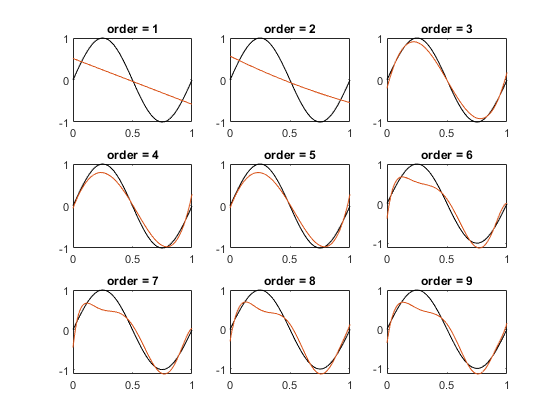


max_order = 9;
mse_train = zeros(max_order,1);
mse_test = zeros(max_order,1);
figure(2);
for order = 1:max_order
    p = polyfit(x_train,y_train,order);
    
    subplot(3,3,order)
    plot(xx,f(xx),'k'); hold on
    plot(xx,polyval(p,xx))
    title(['order = ',num2str(order)])
    mse_train(order) = mean((polyval(p,x_train)-y_train).^2);
    mse_test(order) = mean((polyval(p,x_test)-y_test).^2);
end

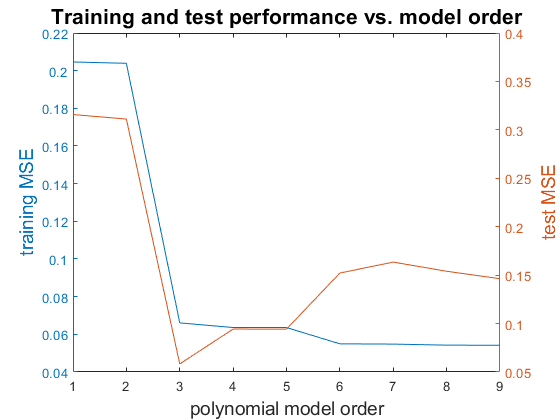


figure(3); 
yyaxis left 
plot(mse_train); 
ylabel('training MSE','FontSize',14)

yyaxis right % plots on same plot with different y-scale on the right
plot(mse_test)
xlabel('polynomial model order','fontsize',14)
ylabel('test MSE','FontSize',14)
title('Training and test performance vs. model order','FontSize',16)

**(2) We can use the holdout method to pick a fitted model that balances accuracy considerations with overfitting considerations. We do this by choosing the polynomial order that yields the lowest test error on the holdout set.**

**For each**$f\left(x\right)$ **option provided, run the above polynomial fitting code a few times with different data. Then answer the following questions for each different **$f$**:**

- **How does the training MSE tend to vary with the fitted polynomial order? Does this make sense? Why or why not?**

- **How does the test MSE vary with the fitted polynomial order? Does this make sense? Why or why not?**

- **What order of polynomial-fitted model has the lowest test error? **(This will vary with the randomly generated data. You could run Monte Carlo on the different sets and choose the one with the lowest mean error, but for this exercise it suffices to run several times and pick an order that consistently achieves among the lowest test errors).

**Linear f(x): training MSE goes down as order increases but test MSE goes up, this makes sense because a more complex model will better fit the noise in the data but will be worse at generalizing for test data, lowest test error with order 1**

**Quadratic f(x): training MSE goes down as order increases but test MSE goes down from order 1 then up, this makes sense because a more complex model will better fit the noise in the data but will be worse at generalizing for test data and the underlying model is of order 2, lowest test error with order 2**

**Sinusoidal f(x): training MSE goes down as order increases but test MSE goes down from order 1 and 2 then up, this makes sense because a more complex model will better fit the noise in the data but will be worse at generalizing for test data and the underlying model is most similar to that of order 3, lowest test error with order 3**